humanInfo = getgenpept('P04626');
yeastInfo = getgenpept('KZV09148');
fungusInfo = getgenpept('QEU58650');
catInfo = getgenpept('AAU01910');
mouseInfo = getgenpept('AAH53078');
orangutanInfo = getgenpept('XP_024090162');
ratInfo = getgenpept('P06494');
dogInfo = getgenpept('NP_001003217');
muniaInfo = getgenpept('XP_021388662');
gorillaInfo = getgenpept('XP_004041868');
peptideInfo = {humanInfo.Sequence, yeastInfo.Sequence, fungusInfo.Sequence, catInfo.Sequence, mouseInfo.Sequence, orangutanInfo.Sequence, ratInfo.Sequence, dogInfo.Sequence, muniaInfo.Sequence, gorillaInfo.Sequence;
               humanInfo.Source, yeastInfo.Source, fungusInfo.Source, catInfo.Source, mouseInfo.Source, orangutanInfo.Source, ratInfo.Source, dogInfo.Source, muniaInfo.Source, gorillaInfo.Source}

peptideInfo = 2×10 cell array
    {'melaalcrwglllallppgaastqvctgtdmklrlpaspethldmlrhlyqgcqvvqgnleltylptnaslsflqdiqevqgyvliahnqvrqvplqrlrivrgtqlfednyalavldngdplnnttpvtgaspgglrelqlrslteilkggvliqrnpqlcyqdtilwkdifhknnqlaltlidtnrsrachpcspmckgsrcwgessedcqsltrtvcaggcarckgplptdccheqcaagctgpkhsdclaclhfnhsgicelhcpalvtyntdtfesmpnpegrytfgascvtacpynylstdvgsctlvcplhnqevtaedgtqrcekcskpcarvcyglgmehlrevravtsaniqefagckkifgslaflpesfdgdpasntaplqpeqlqvfetleeitgylyisawpdslpdlsvfqnlqvirgrilhngaysltlqglgiswlglrslrelgsglalihhnthlcfvhtvpwdqlfrnphqallhtanrpedecvgeglachqlcarghcwgpgptqcvncsqflrgqecveecrvlqglpreyvnarhclpchpecqpqngsvtcfgpeadqcvacahykdppfcvarcpsgvkpdlsympiwkfpdeegacqpcpincthscvdlddkgcpaeqraspltsiisavvgillvvvlgvvfgilikrrqqkirkytmrrllqetelvepltpsgampnqaqmrilketelrkvkvlgsgafgtvykgiwipdgenvkipvaikvlrentspkankeildeayvmagvgspyvsrllgicltstvqlvtqlmpygclldhvrenrgrlgsqdllnwcmqiakgmsyledvrlvhrdlaarnvlvkspnhvkitdfglarlldideteyhadggkvpikwmalesilrrrfthqsdvwsygvtvwelmtfgakpydgipareipdllekgerlpqppictidvymimvkcwmidse

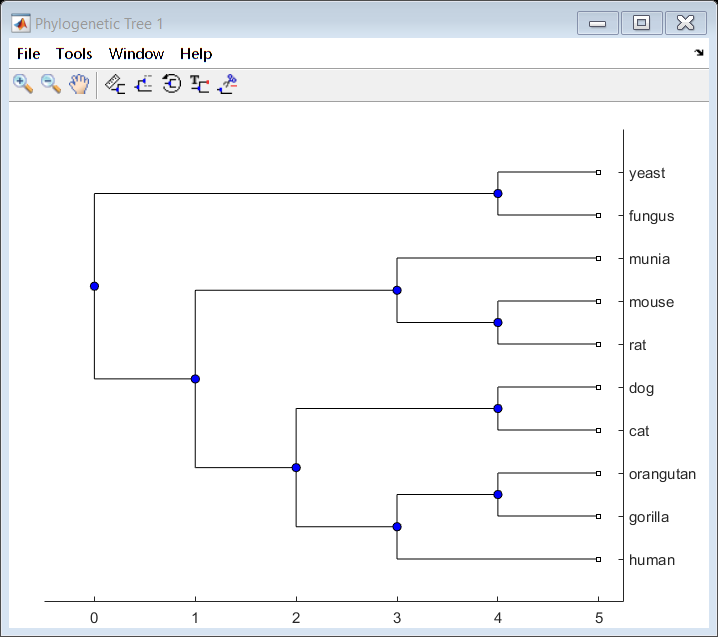

numberOfSpecies = length(peptideInfo(1));
           
featureTree = phytree([1, 2; 4, 5; 6, 7; 8, 9; 3, 12; 14, 10; 13, 16; 15, 17; 11, 18], {'yeast', 'fungus', 'munia', 'mouse', 'rat', 'dog', 'cat', 'orangutan', 'gorilla', 'human'});  
view(featureTree);


scoreMatrix = zeros(numberOfSpecies, numberOfSpecies);
for i = 1 : numberOfSpecies
    for j = 1 : numberOfSpecies
        scoreMatrix(i, j) = nwalign(peptideInfo(1, i), peptideInfo(1, j));
    end
end
scoreMatrix

scoreMatrix = 2945

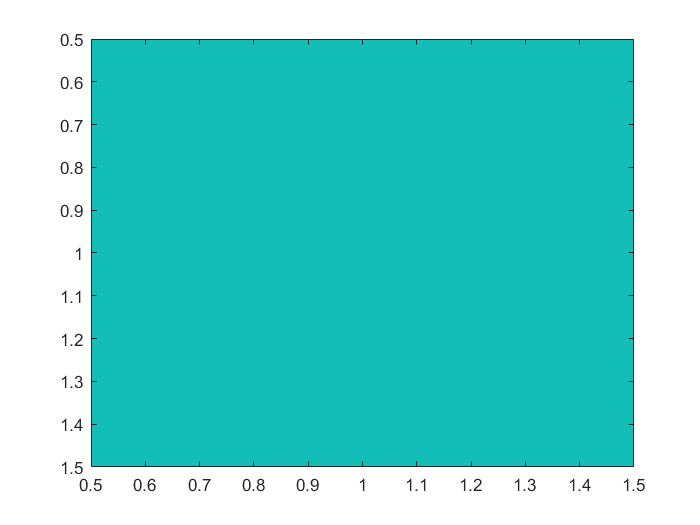

colourMap1 = imagesc(scoreMatrix);


distances = seqpdist(peptideInfo(1, :), 'SquareForm', true)

distances =          0    1.8716    1.8434    1.5338    0.7423    0.0362    0.1274    0.0734    0.3969    0.0024
    1.8716         0    0.5984    1.7784    1.7917    1.8670    1.8236    1.8825    1.8853    1.8602
    1.8434    0.5984         0    1.6858    1.7571    1.8841    1.8455    1.8542    1.9092    1.8490
    1.5338    1.7784    1.6858         0    1.8392    1.5452    1.5277    1.5306    1.5428    1.5338
    0.7423    1.7917    1.7571    1.8392         0    0.7807    0.6426    0.7570    1.0027    0.7458
    0.0362    1.8670    1.8841    1.5452    0.7807         0    0.1507    0.0924    0.4101    0.0370
    0.1274    1.8236    1.8455    1.5277    0.6426    0.1507         0    0.1232    0.4053    0.1292
    0.0734    1.8825    1.8542    1.5306    0.7570    0.0924    0.1232         0    0.3961    0.0751
    0.3969    1.8853    1.9092    1.5428    1.0027    0.4101    0.4053    0.3961         0    0.3969
    0.0024    1.8602    1.8490    1.5338    0.7458    0.0370    0.1292    0.075

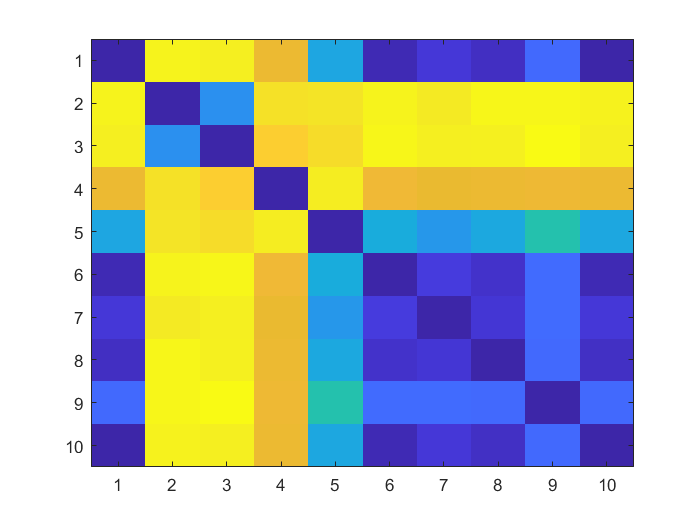

colourMap2 = imagesc(distances);

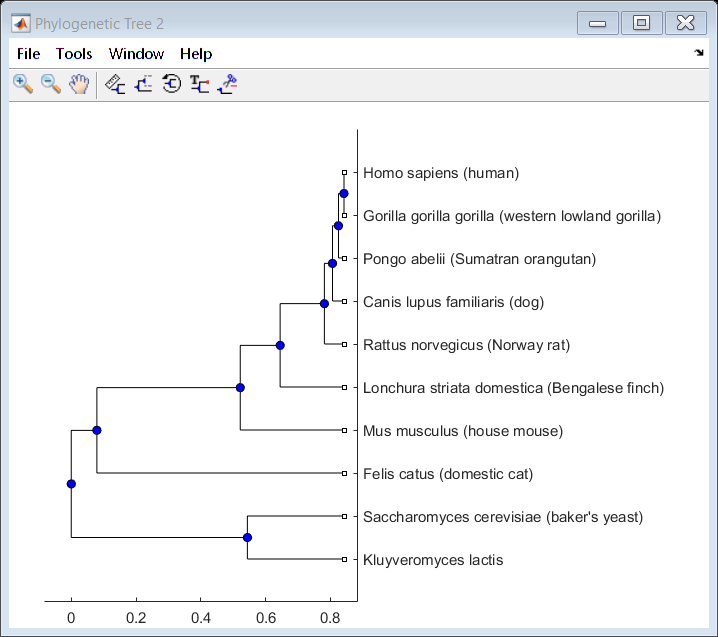


phylogeneticTree = seqlinkage(distances, 'single', peptideInfo(2, :));
view(phylogeneticTree)